# Generate Beam Pattern Sampled data for Reconstruction

#### Load array data

%load the array microphone positions (and all other data)
load("Sub Functions and Data\AcousticTunnelBasicGeometry.mat")

%get the points (from the array data)
evalPoints = arrayFullGeomData.micPositions;

#### Set input position and beam pattern

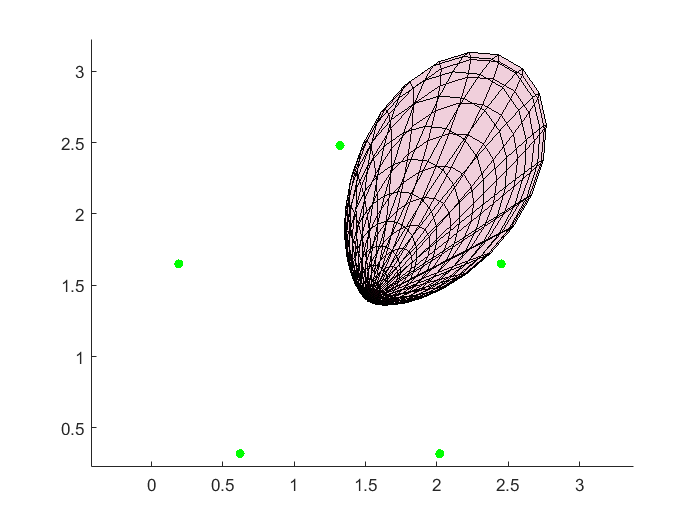

%set a bat orientation
randBatOrientation = [rand;rand;rand];
randBatOrientation = randBatOrientation/norm(randBatOrientation);

%set the bat position
randBatPos = arrayFullGeomData.centerPoint + [0.2,0.1,0.2];

%the source variables
sourceVars = struct("Location",randBatPos,"Direction",randBatOrientation);

%the beam pattern variables
phiSpan = -pi:0.1:pi;
thetaSpan = -pi:0.1:pi;
beamPatternVars = struct("Amp",2,"Sigx",pi/6,"Sigy",pi/6,"Vo",0,"phiSpan",phiSpan,"thetaSpan",thetaSpan);

%generate the beam pattern here
[beamPatternLin,beamPatternSph] = generateBeamPatternBasic(sourceVars,beamPatternVars);

%draw everything
figure(1)
clf
hold on
%drawVector([0,0,0],randBatOrientation','r',3);
surf(beamPatternSph.X,beamPatternSph.Y,beamPatternSph.Z,'FaceAlpha',0.1,'FaceColor',rand([1 3]));
scatter3(evalPoints(:,1),evalPoints(:,2),evalPoints(:,3),30,"green","filled");
axis equal

%plot the beam pattern here

#### Compute the signal amplitudes at points

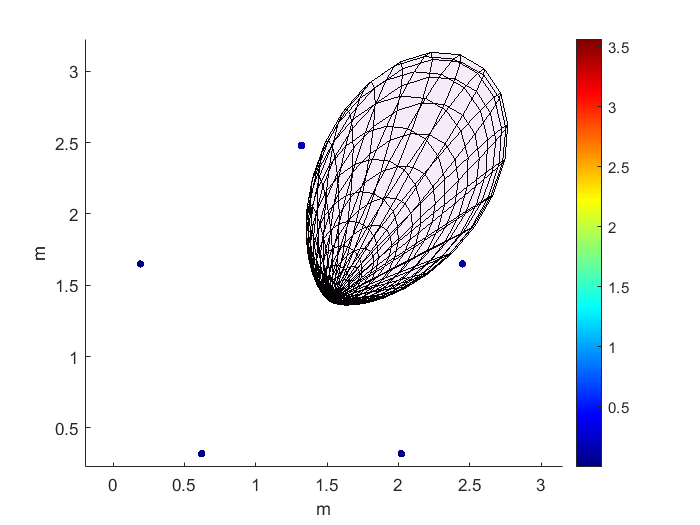

%generate the signals
%fft, reverse and get the signal, then phase shift by distance and compute
%the decay

%the signal frequency amplitudes
sigAmplitudes = [];

%the radial dropoff due to 1/r squared
radDropoffAmplitudes = [];

%the time phase (delay in seconds)
timePhase = [];

%for each point
for i = 1:size(evalPoints,1)
    %for each point, compute the azimuth angle and distance
    [th,ro,r] = cart2sph(evalPoints(i,1) - randBatPos(1),evalPoints(i,2)  - randBatPos(2),evalPoints(i,3) - randBatPos(3));

    %get the amplitude at that point
    ampAtPoint = interp2(beamPatternVars.thetaSpan,beamPatternVars.phiSpan,beamPatternLin.amplitude,th,ro);
    
    %add all these to the signal frequency amplitudes
    sigAmplitudes = [sigAmplitudes;ampAtPoint];
    
    %radial dropoff
    radDropoffAmplitudes = [radDropoffAmplitudes; 1/(r^2)];
    
    %the time phase
    timePhase = [timePhase; r/343];
end

%show the signal amplitudes calculated (and the beam pattern)
figure(2)
clf
hold on
scatter3(evalPoints(:,1),evalPoints(:,2),evalPoints(:,3),20,sigAmplitudes,'filled');
surf(beamPatternSph.X,beamPatternSph.Y,beamPatternSph.Z,'FaceAlpha',0.05,'FaceColor',rand([1 3]));
colormap("jet")
colorbar
axis equal
xlabel('m')
ylabel('m')
zlabel('m')

#### Reconstruct the signal

%set the timespan
tSpan = 3;

%set the sampling frequency
sigFs = 1e5;

%chirp frequency
chirpFreq = 20e3;

%set the basic signal
%generate a short chirp
soundSignal = linspace(0,3,sigFs*tSpan);
soundSignal = 2*sin(2*pi*chirpFreq*soundSignal);
soundSignal(1:round(length(soundSignal)*0.5)) = 0*soundSignal(1:round(length(soundSignal)*0.5));
soundSignal(round(length(soundSignal)*0.8):end) = 0*soundSignal(round(length(soundSignal)*0.8:end));

%store the reconstructed signals
reconstructedSignals = [];

%reconstruct the signals now
for i = 1:size(evalPoints,1)
    
    %compute the delay
    sigDelay = round(timePhase(i)*sigFs);
    
    %get the signal at the sigDelay point then go from the start to the end
    delayedSig = soundSignal(sigDelay:end);
    
    %the zeroed signal
    zeroSignal = 0*soundSignal;
    zeroSignal(1:length(delayedSig)) = delayedSig;
    
    %set the signal
    reconstructedSignals = [reconstructedSignals;zeroSignal];
end

